# Laboratorium nr. 11

Przetwarzanie sygnałów cyfrowych

Filip Pasternak, grupa lab. 7, piątek 18:30

## Zadanie 1

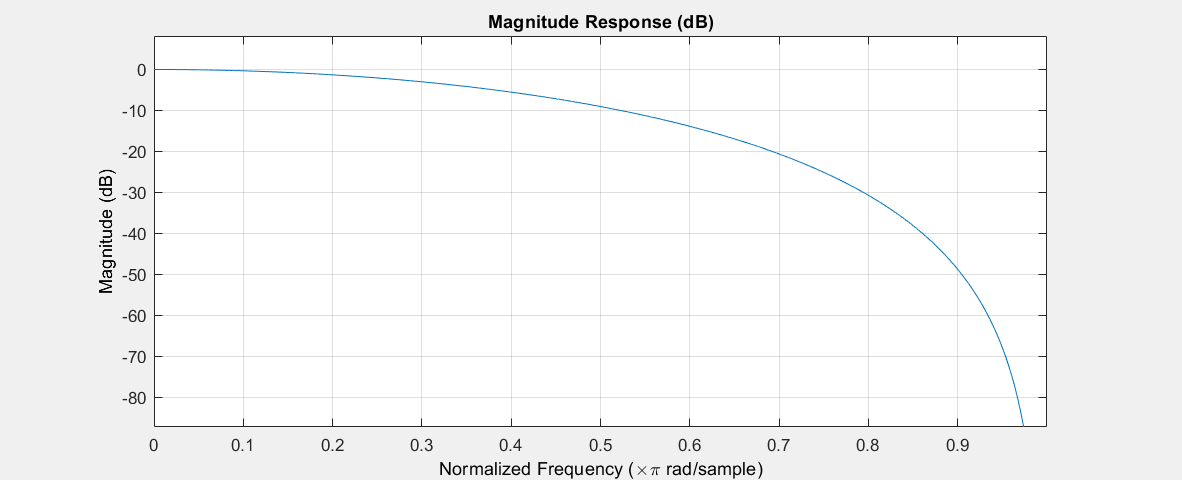

clear all

%1
[b,a] = maxflat(4,1,0.3); 
fvtool(b,a);

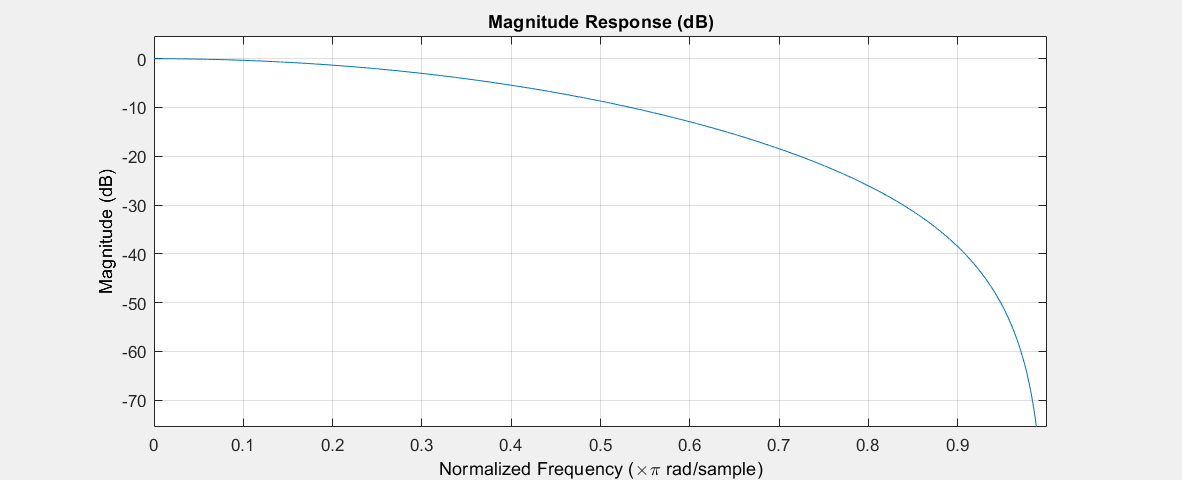


%2
[b, a] = maxflat(4,'sym',0.3);
fvtool(b,a);

## Zadanie 2

clear all

b = [1 -0.5];
a = [1 -2];
act_flag1 = isstable(b,a)

act_flag1 = logical
   0


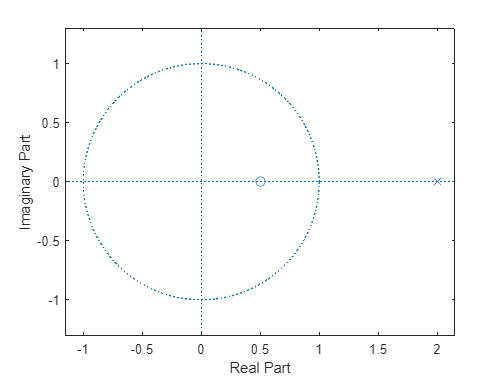

zplane(b,a)

Wynik flag = 0 oznacza, że filtr jest niestabilny

## Zadanie 3

clear all

b = [1 -0.1];
a = [-1 -0.1];
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


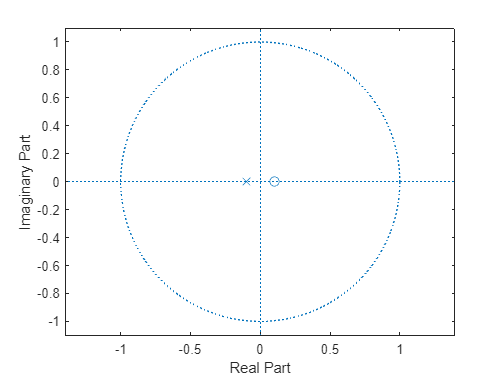

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 4

clear all

b = [0.9 -0.8];
a = [-0.9 -0.8];
act_flag1 = isstable(b,a)

act_flag1 = logical
   1


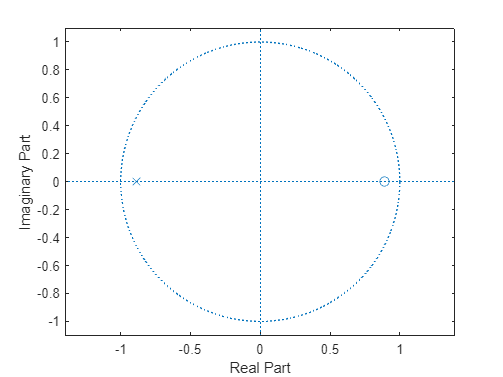

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 5

clear all

b = [0.9 -0.8 1 1];
a = [-0.9 -0.8 -1];
act_flag1 = isstable(b,a)

act_flag1 = logical
   0


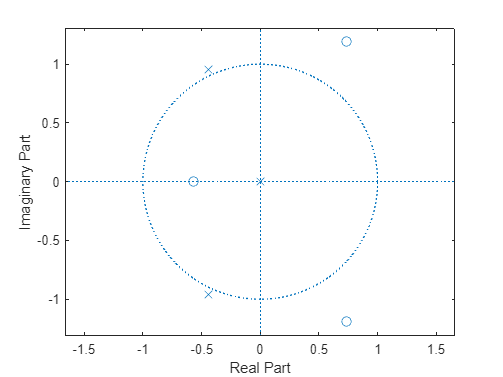

zplane(b,a)

Wynik flag = 0 oznacza, że filtr jest niestabilny

## Zadanie 6

m = [0 0 1 1 1 0 1 1 0 0];
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1]; 
[b,a] = yulewalk(10,f,m); 

act_flag1 = isstable(b,a)

act_flag1 = logical
   1


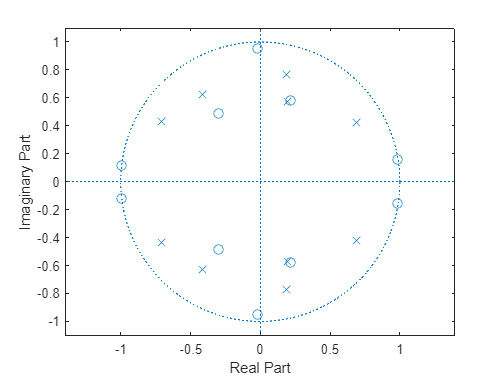

zplane(b,a)

Wynik flag = 1 oznacza, że filtr jest stabilny

## Zadanie 7

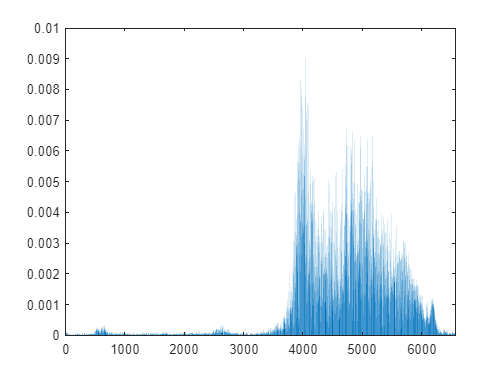

load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

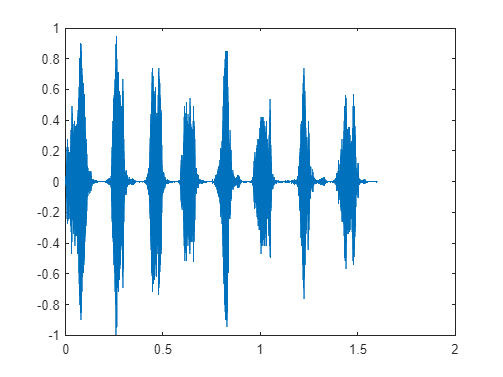

plot(t,y); 

## Zadanie 8

figure;
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]); 

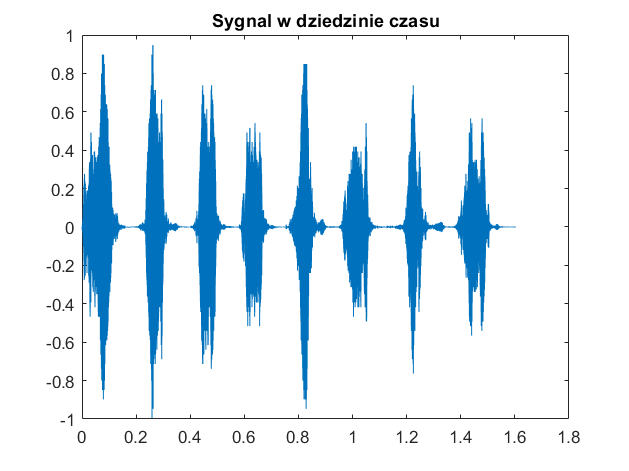

plot(t,y);
title('Sygnal w dziedzinie czasu');

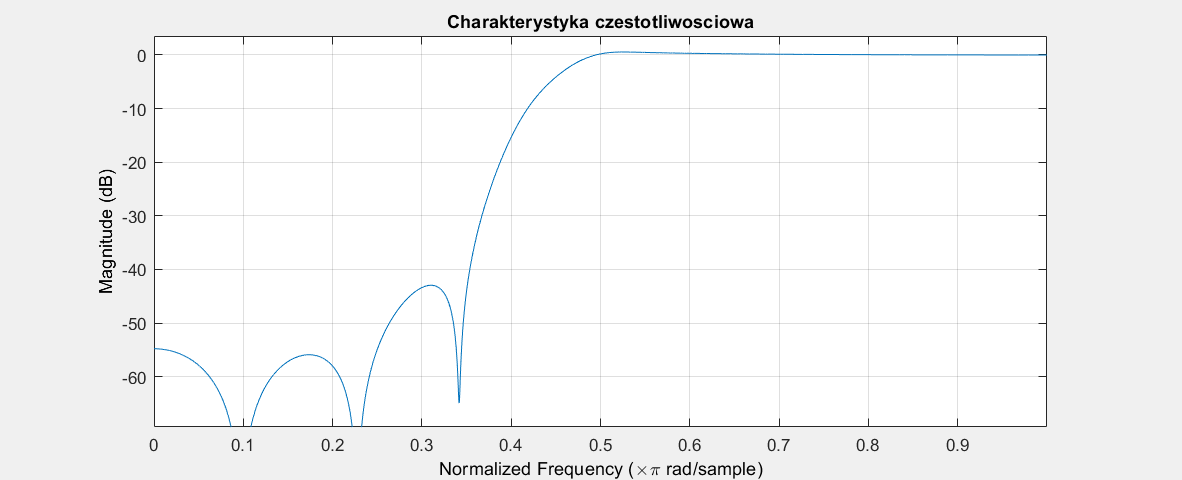


m = [0   0   0   0   0   1   1   1   1 1]; 
f = [0 0.1 0.2 0.3 0.4 0.5 0.7 0.8 0.9 1]; 
[b,a] = yulewalk(10,f,m);
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

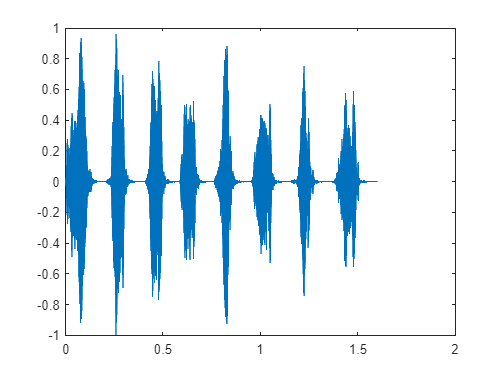


out = filter(b,a,y);
plot(t, out); 

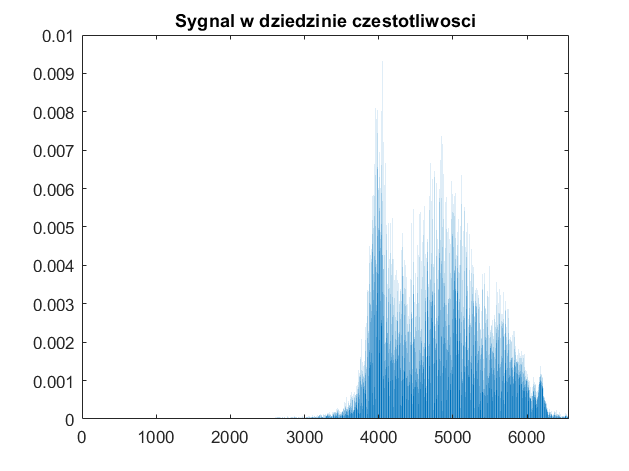

xfft=abs(fft(out)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564));  
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

## Zadanie 9

figure;
load chirp
t = (0:length(y)-1)/Fs; % 1.6 sekundy
xfft=abs(fft(y)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]); 

plot(t,y);
title('Sygnal w dziedzinie czasu');

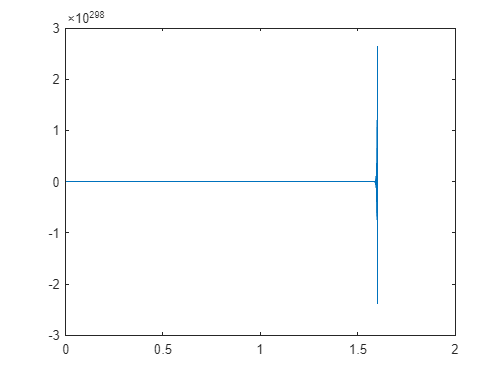


b = [0.9 -0.8 1 1];
a = [-0.9 -0.8 -1];
fvtool(b,a)
title('Charakterystyka czestotliwosciowa');

out = filter(b,a,y);
plot(t, out); 

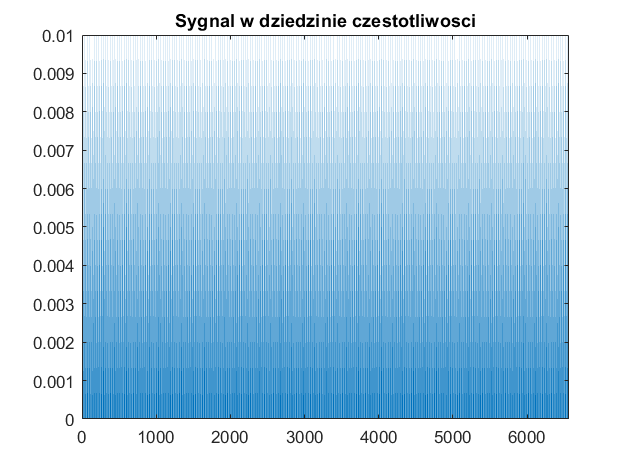

xfft=abs(fft(out)); 
xfft=xfft/13129; 
x1=1:1:6564; 
bar(x1(1:6564), xfft(1:6564));  
axis([0,6564, 0,0.01]) ;
title('Sygnal w dziedzinie czestotliwosci');

## Zadanie 10

load chirp
[n,Wn] = buttord([2000 3000]/5000,[500 4500]/5000,1,60)

n = 4

Wn =     0.3406    0.6594


[b,a] = butter(n,Wn);
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]) ;

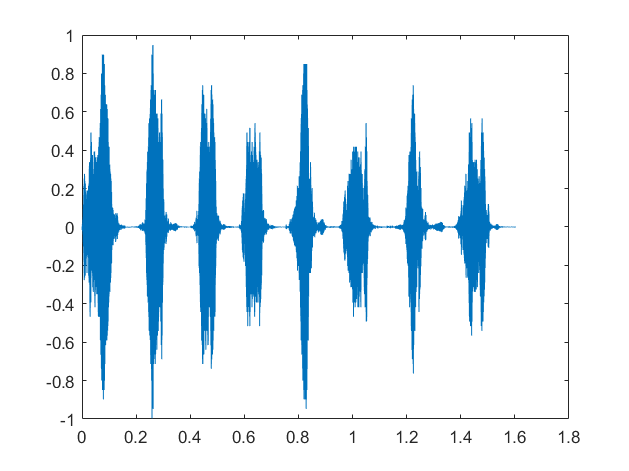

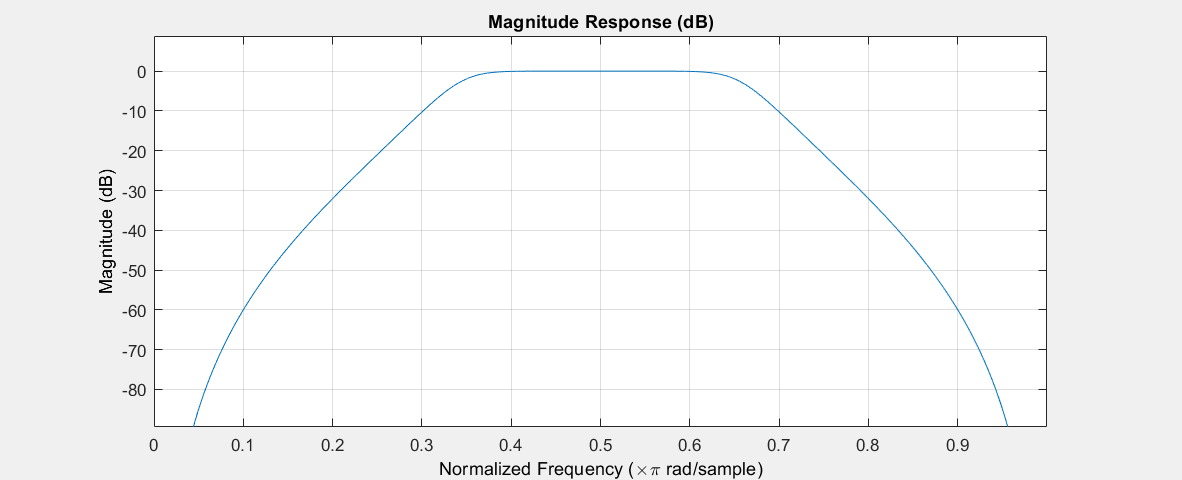


plot(t,y);
fvtool(b,a);

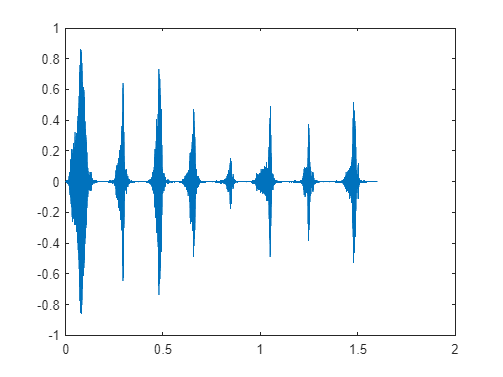


outsignal = filter(b,a,y);
plot(t, outsignal);

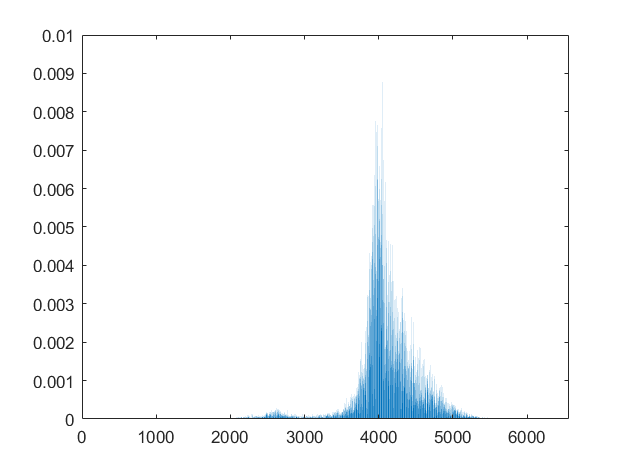


xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zadanie 11

load chirp
[n,Wn] = buttord([2000 3000]/5000,[1800 3200]/5000,1,60)

n = 21

Wn =     0.3961    0.6039


[b,a] = butter(n,Wn);
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]) ;

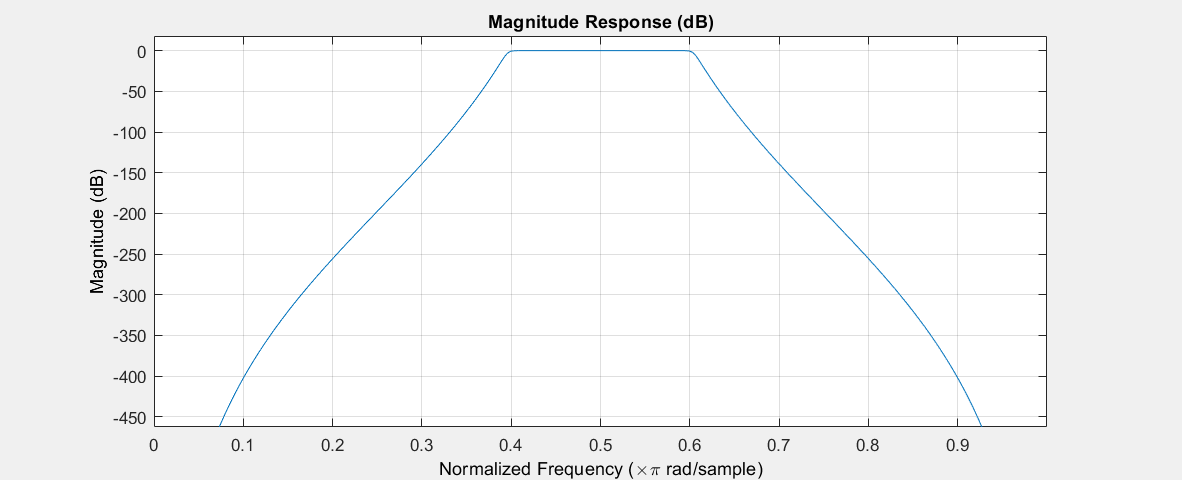


plot(t,y);
fvtool(b,a);

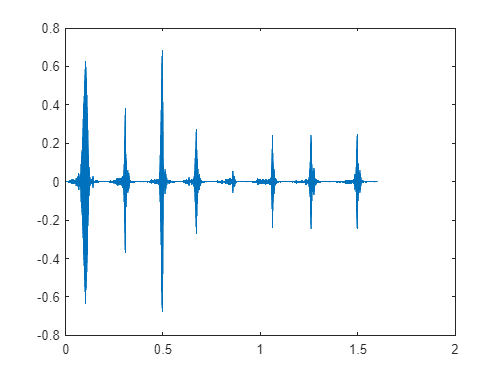


outsignal = filter(b,a,y);
plot(t, outsignal);

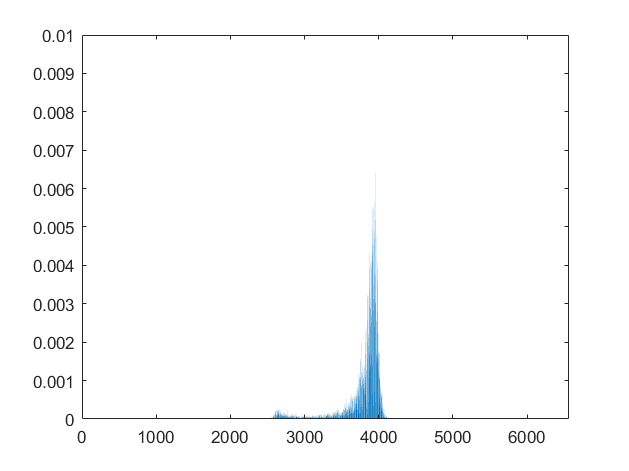


xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zadanie 12

load chirp
[n,Wn] = ellipord([2200 2700]/5000,[2000 2900]/5000,1,60) 

n = 5

Wn =     0.4400    0.5400


[b,a] = ellip(n,1,60,Wn); 
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]) ;

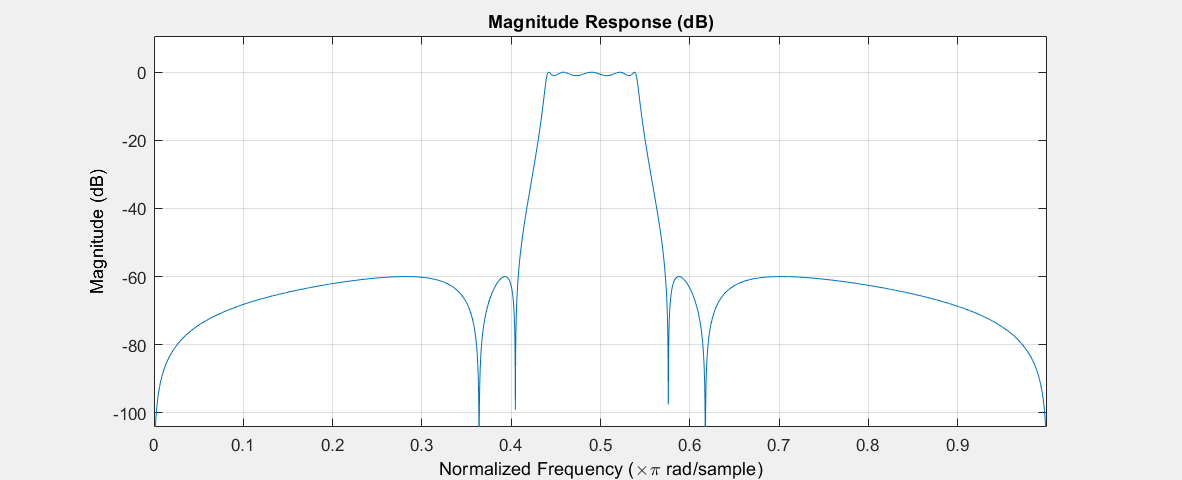


plot(t,y);
fvtool(b,a);

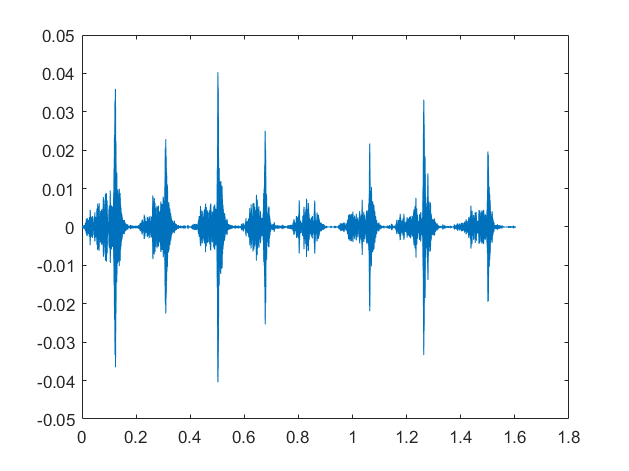


outsignal = filter(b,a,y);
plot(t, outsignal);

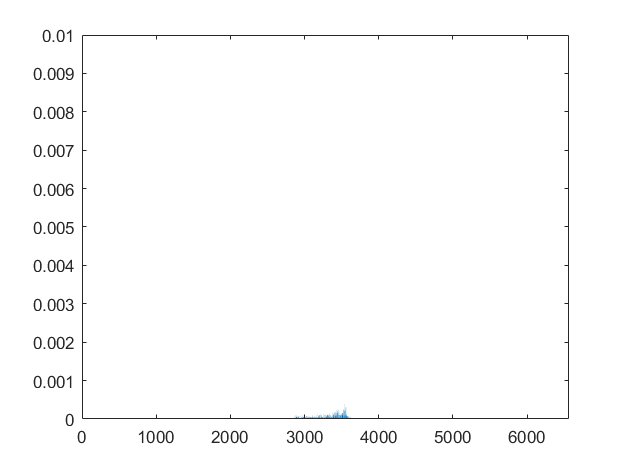


xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zadanie 13

load chirp
[n,Wn] = ellipord([1000 4000]/5000,[900 4100]/5000,1,60)

n = 8

Wn =     0.2000    0.8000


[b,a] = ellip(n,1,60,Wn); 
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564))
axis([0,6564, 0,0.01]) ;


plot(t,y);
fvtool(b,a);

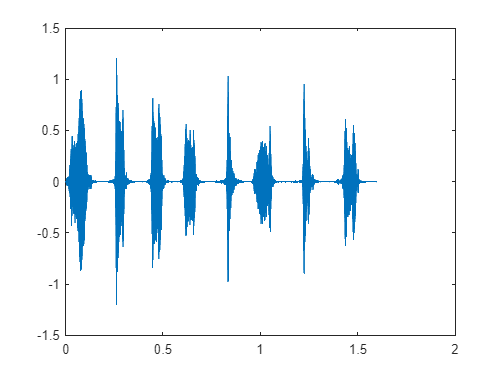


outsignal = filter(b,a,y);
plot(t, outsignal);

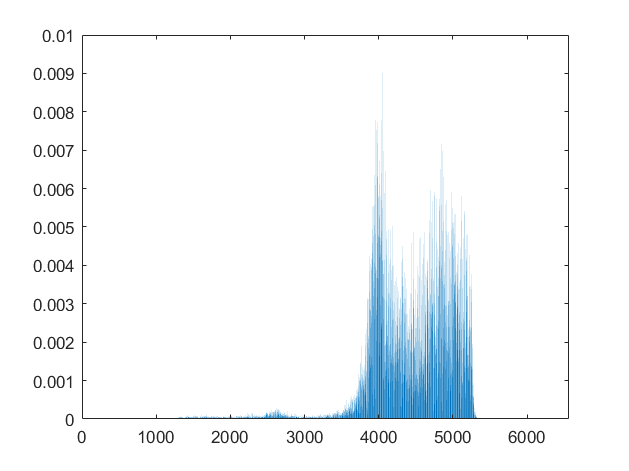


xfft=abs(fft(outsignal));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));
axis([0,6564, 0,0.01]) ;

## Zadanie 14

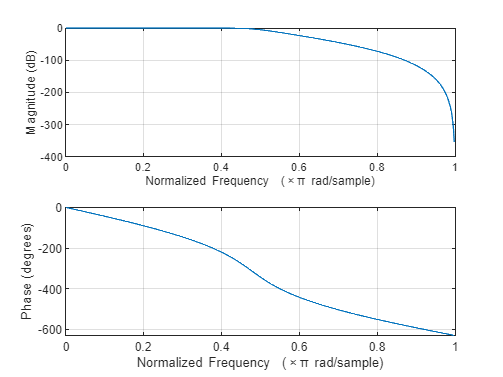

load chirp
t = (0:length(y)-1)/Fs;
[zhi,phi,khi] = butter(7,0.48,'low');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)

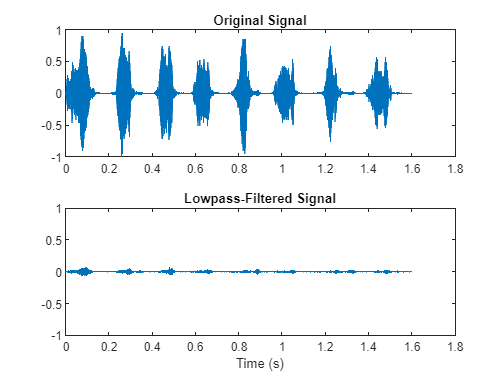


outhi = sosfilt(soshi,y);
figure
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Highpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)
[zlo,plo,klo] = butter(7,0.48);
soslo = zp2sos(zlo,plo,klo);
outlo = sosfilt(soslo,y);
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outlo)
title('Lowpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)

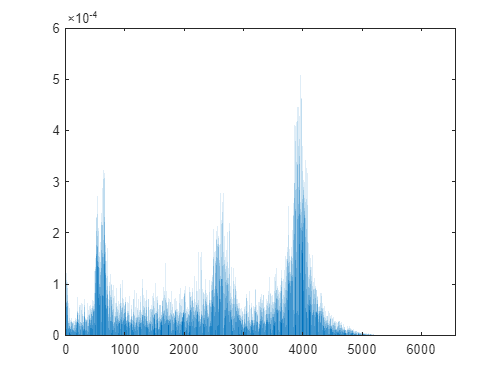


figure
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));

## Zadanie 15

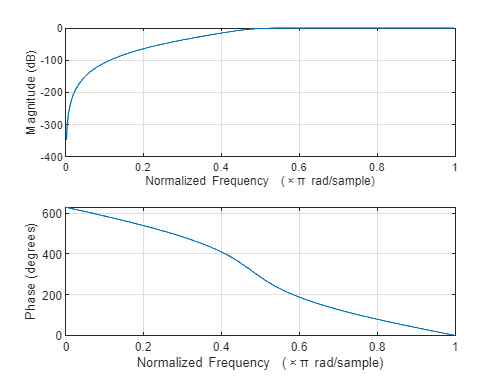

load chirp
t = (0:length(y)-1)/Fs;
[zhi,phi,khi] = butter(7,0.48,'high');
soshi = zp2sos(zhi,phi,khi);
freqz(soshi)

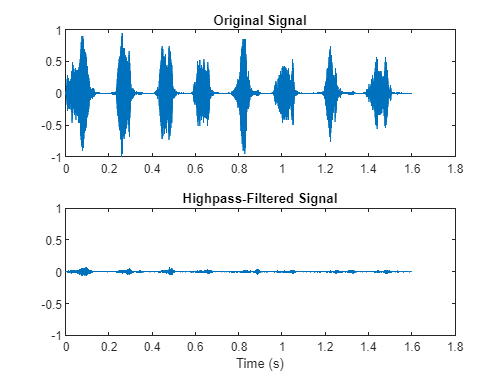


outhi = sosfilt(soshi,y);
figure
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outhi)
title('Highpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)
[zlo,plo,klo] = butter(7,0.48);
soslo = zp2sos(zlo,plo,klo);
outlo = sosfilt(soslo,y);
subplot(2,1,1)
plot(t,y)
title('Original Signal')
ys = ylim;
subplot(2,1,2)
plot(t,outlo)
title('Highpass-Filtered Signal')
xlabel('Time (s)')
ylim(ys)

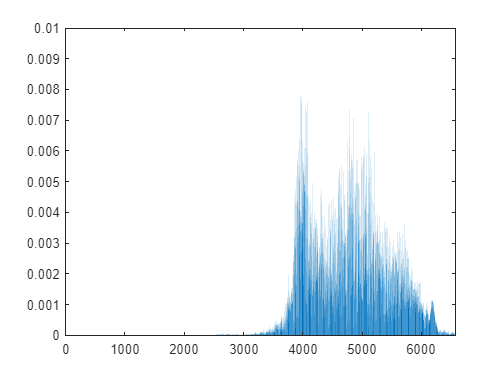


figure
xfft=abs(fft(y));
xfft=xfft/13129;
x1=1:1:6564;
xfft=abs(fft(outhi));
xfft=xfft/13129;
x1=1:1:6564;
bar(x1(1:6564), xfft(1:6564));

## Pytania

1. Informacje na temat w jaki sposób projektujemy filtry IIR.

W przypadku filtrów o nieskończonej odpowiedzi impulsowej pożądane współczynniku filtru są dokłądnie równe wartościom poszczególnych próbek opowiedzi impulsowej. Do projektowania filtrów IIR najlepiej użyć odpowiedniego oprogramowania. 

2. Różnice między filtrami FIR i IIR.

Filtry IIr zapewniają szybkie działanie, niestety kosztem nieliniowości fazy. Muszą być odgórnie zaprojektowane jako stabilne. Filtry FIR natomiast zapewniają nam stabilność oraz liniowość fazy, ale są obciążające obliczeniowo. 

3. Kiedy bardziej wskazane jest użycie filtru FIR a kiedy filtru IIR? 

Użycie filtru FIR jest bardziej wskazane niż użycie filtru IIR, gdy potrzebujemy filtru o dokładnie liniowej fazie. 

4. Czy są jakieś różnice w budowie filtrów FIR i IIR

Tak, występują różnice w budowie filtrów FIR i IIR. Między innymi filtr FIR korzysta tylko z próbek przeszłych sygnału wejściowego, natomiast filtr IRR korzystają również z próbek przeszłych sygnału wyjściowego.